
% 测试Jacobi和Gauss-Seidel迭代法
    rng(23);
    fprintf('=== 迭代法测试 ===\n\n');

=== 迭代法测试 ===



    
    % 测试用例1: 严格对角占优矩阵 
    fprintf('测试用例1: 严格对角占优矩阵 \n');

测试用例1: 严格对角占优矩阵 


    n = 30^2;
    max_iter = 1e3;
    
    % 生成严格对角占优矩阵
    A1 = diag(ones(n,1) * (n + 1));  % 对角线元素为 n+1
    for i = 1:n
        for j = 1:n
            if i ~= j
                A1(i,j) = -1;  % 非对角线元素为 -1
            end
        end
    end
    
    % 生成右端向量，确保有解
    x_exact = ones(n, 1);  % 精确解设为全1向量
    b1 = A1 * x_exact;
    
    x0 = zeros(n, 1);  % 初始猜测为全0向量
    
    fprintf('矩阵维度: %d x %d\n', n, n);

矩阵维度: 900 x 900


    fprintf('对角线 dominance: 对角线元素 = %d, 非对角线元素和 = %d\n', n+1, n-1);

对角线 dominance: 对角线元素 = 901, 非对角线元素和 = 899


    
    % 检查收敛性
    fprintf('检查收敛性:\n');

检查收敛性:


    D1 = diag(diag(A1));
    R_jacobi1 = eye(n) - D1 \ A1;
    spectral_radius_jacobi1 = max(abs(eig(R_jacobi1)));
    fprintf('Jacobi迭代矩阵谱半径: %.6f\n', spectral_radius_jacobi1);

Jacobi迭代矩阵谱半径: 0.997780


    
    L1 = tril(A1, -1);
    U1 = triu(A1, 1);
    G_gs1 = -(D1 + L1) \ U1;
    spectral_radius_gs1 = max(abs(eig(G_gs1)));
    fprintf('Gauss-Seidel迭代矩阵谱半径: %.6f\n', spectral_radius_gs1);

Gauss-Seidel迭代矩阵谱半径: 0.995567



    % Jacobi迭代
    fprintf('\n--- Jacobi迭代 ---\n');


--- Jacobi迭代 ---


    tic;
    [x_jacobi, iter_jacobi, error_jacobi] = jacobi_iteration(A1, b1, x0, max_iter, 1e-8);
    time_jacobi = toc;
    fprintf('迭代次数: %d\n', iter_jacobi);

迭代次数: 1000


    fprintf('计算时间: %.4f 秒\n', time_jacobi);

计算时间: 0.0797 秒


    fprintf('与精确解的误差: %e\n', norm(x_jacobi - x_exact));

与精确解的误差: 3.251038e+00


    fprintf('最终相对误差: %e\n', error_jacobi(end));

最终相对误差: 2.703867e-04


    
    % Gauss-Seidel迭代
    fprintf('\n--- Gauss-Seidel迭代 ---\n');


--- Gauss-Seidel迭代 ---


    tic;
    [x_gs, iter_gs, error_gs] = gauss_seidel_iteration(A1, b1, x0, max_iter, 1e-8);
    time_gs = toc;
    fprintf('迭代次数: %d\n', iter_gs);

迭代次数: 1000


    fprintf('计算时间: %.4f 秒\n', time_gs);

计算时间: 3.1476 秒


    fprintf('与精确解的误差: %e\n', norm(x_gs - x_exact));

与精确解的误差: 3.531492e-01


    fprintf('最终相对误差: %e\n', error_gs(end));

最终相对误差: 5.315614e-05


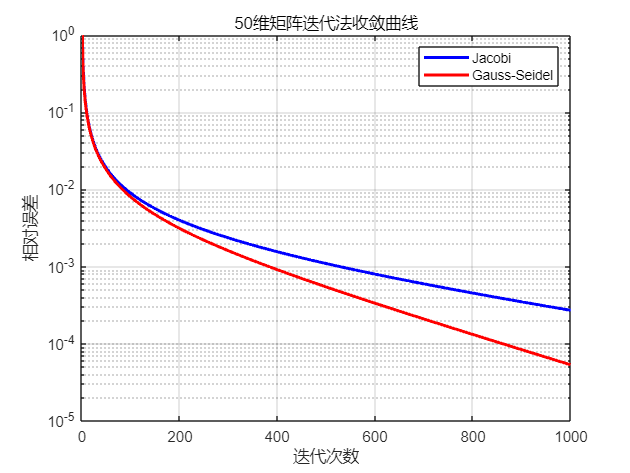

    
    % 绘制收敛曲线
    figure;
    semilogy(1:iter_jacobi, error_jacobi, 'b-', 'LineWidth', 2, 'DisplayName', 'Jacobi');
    hold on;
    semilogy(1:iter_gs, error_gs, 'r-', 'LineWidth', 2, 'DisplayName', 'Gauss-Seidel');
    xlabel('迭代次数');
    ylabel('相对误差');
    title('50维矩阵迭代法收敛曲线');
    legend('show');
    grid on;

    
    fprintf('\n收敛速度比较:\n');


收敛速度比较:


    fprintf('Jacobi迭代次数: %d, 时间: %.4f秒\n', iter_jacobi, time_jacobi);

Jacobi迭代次数: 1000, 时间: 0.0797秒


    fprintf('Gauss-Seidel迭代次数: %d, 时间: %.4f秒\n', iter_gs, time_gs);

Gauss-Seidel迭代次数: 1000, 时间: 3.1476秒


    fprintf('Gauss-Seidel加速比: %.2f倍\n', time_jacobi / time_gs);

Gauss-Seidel加速比: 0.03倍


    
    % 测试用例2: 对称正定矩阵 
    fprintf('\n\n测试用例2: 对称正定矩阵 \n');



测试用例2: 对称正定矩阵 


    
    % 生成对称正定矩阵
    A2 = gallery('poisson', realsqrt(n));  % 使用Poisson问题矩阵

    % 生成右端向量
    x_exact2 = randn(n, 1);  % 随机精确解
    b2 = A2 * x_exact2;
    
    fprintf('矩阵维度: %d x %d\n', n, n);

矩阵维度: 900 x 900


    fprintf('矩阵条件数: %.2e\n', cond(A2));

矩阵条件数: 5.65e+02



    % 检查收敛性
    fprintf('检查收敛性:\n');

检查收敛性:


    D2 = diag(diag(A2));
    R_jacobi2 = eye(n) - D2 \ A2;
    spectral_radius_jacobi2 = max(abs(eig(R_jacobi2)));
    fprintf('Jacobi迭代矩阵谱半径: %.6f\n', spectral_radius_jacobi2);

Jacobi迭代矩阵谱半径: 0.994869


    
    L2 = tril(A2, -1);
    U2 = triu(A2, 1);
    G_gs2 = -(D2 + L2) \ U2;
    spectral_radius_gs2 = max(abs(eigs(G_gs2)));
    fprintf('Gauss-Seidel迭代矩阵谱半径: %.6f\n', spectral_radius_gs2);

Gauss-Seidel迭代矩阵谱半径: 0.989765



    % Jacobi迭代
    fprintf('\n--- Jacobi迭代 ---\n');


--- Jacobi迭代 ---


    tic;
    [x_jacobi2, iter_jacobi2, error_jacobi2] = jacobi_iteration(A2, b2, x0, max_iter, 1e-6);
    time_jacobi2 = toc;
    fprintf('迭代次数: %d\n', iter_jacobi2);

迭代次数: 1000


    fprintf('计算时间: %.4f 秒\n', time_jacobi2);

计算时间: 0.0715 秒


    fprintf('与精确解的误差: %e\n', norm(x_jacobi2 - x_exact2));

与精确解的误差: 1.417592e-02


    fprintf('最终相对误差: %e\n', error_jacobi2(end));

最终相对误差: 1.220733e-05


    
    % Gauss-Seidel迭代
    fprintf('\n--- Gauss-Seidel迭代 ---\n');


--- Gauss-Seidel迭代 ---


    tic;
    [x_gs2, iter_gs2, error_gs2] = gauss_seidel_iteration(A2, b2, x0, max_iter, 1e-6);
    time_gs2 = toc;
    fprintf('迭代次数: %d\n', iter_gs2);

迭代次数: 598


    fprintf('计算时间: %.4f 秒\n', time_gs2);

计算时间: 3.6972 秒


    fprintf('与精确解的误差: %e\n', norm(x_gs2 - x_exact2));

与精确解的误差: 5.228737e-03


    fprintf('最终相对误差: %e\n', error_gs2(end));

最终相对误差: 9.970563e-07


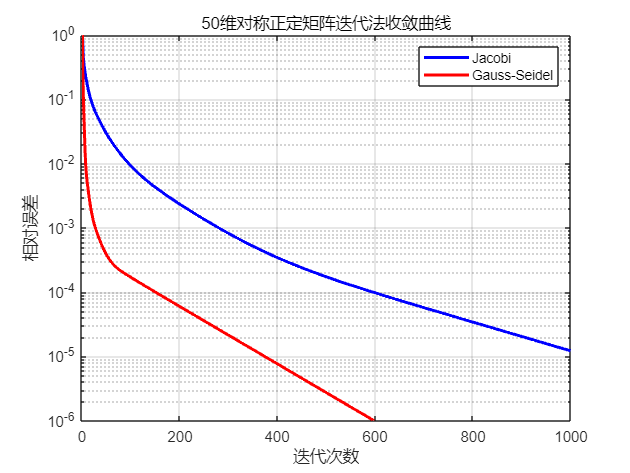

    
    % 绘制第二个测试用例的收敛曲线
    figure;
    semilogy(1:iter_jacobi2, error_jacobi2, 'b-', 'LineWidth', 2, 'DisplayName', 'Jacobi');
    hold on;
    semilogy(1:iter_gs2, error_gs2, 'r-', 'LineWidth', 2, 'DisplayName', 'Gauss-Seidel');
    xlabel('迭代次数');
    ylabel('相对误差');
    title('50维对称正定矩阵迭代法收敛曲线');
    legend('show');
    grid on;

    
    fprintf('\n收敛速度比较:\n');


收敛速度比较:


    fprintf('Jacobi迭代次数: %d, 时间: %.4f秒\n', iter_jacobi2, time_jacobi2);

Jacobi迭代次数: 1000, 时间: 0.0715秒


    fprintf('Gauss-Seidel迭代次数: %d, 时间: %.4f秒\n', iter_gs2, time_gs2);

Gauss-Seidel迭代次数: 598, 时间: 3.6972秒


    fprintf('Gauss-Seidel加速比: %.2f倍\n', time_jacobi2 / time_gs2);

Gauss-Seidel加速比: 0.02倍
